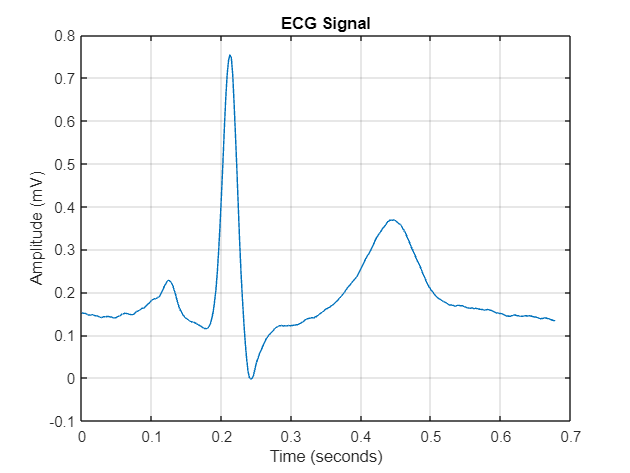


% Load ECG signal data from the .mat file
data = load("ECG_template.mat");

% ECG data
ECG = data.ECG_template;

% Defining parameters
fs = 500;         
Ts = 1/fs;
n = length(ECG);

% Create time vector based on the sampling frequency
time = (0:n-1)*Ts;

% Plot the ECG signal
figure;
plot(time, ECG);
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('ECG Signal');
grid on;


disp(ECG)

    0.1517    0.1507    0.1507    0.1494    0.1477    0.1467    0.1465    0.1477    0.1474    0.1461    0.1444    0.1449    0.1434    0.1417    0.1408    0.1414    0.1432    0.1423    0.1436    0.1432    0.1424    0.1422    0.1403    0.1400    0.1403    0.1412    0.1435    0.1442    0.1469    0.1493    0.1500    0.1510    0.1500    0.1498    0.1485    0.1478    0.1477    0.1478    0.1515    0.1547    0.1560    0.1574    0.1605    0.1625    0.1625    0.1649    0.1679    0.1714    0.1735    0.1773    0.1812    0.1829    0.1848    0.1843    0.1875    0.1884    0.1921    0.1988    0.2056    0.2137    0.2192    0.2254    0.2282    0.2259    0.2228    0.2168    0.2057    0.1955    0.1826    0.1715    0.1614    0.1553    0.1500    0.1442    0.1403    0.1388    0.1360    0.1328    0.1318    0.1301    0.1300    0.1282    0.1269    0.1243    0.1232    0.1208    0.1187    0.1165    0.1154    0.1146    0.1156    0.1202    0.1268    0.1382    0.1540    0.1776    0.2061    0.2474    0.3003    0.3608

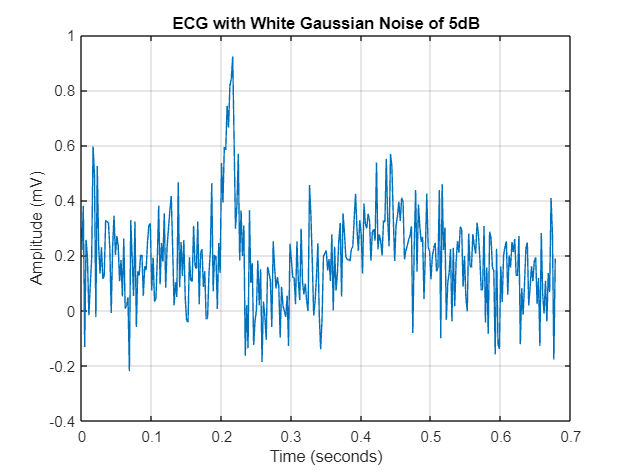

% Add white Gaussian noise of 5dB
SNR = 5;
rng(0);
nECG = awgn(ECG,SNR,'measured');

figure;
plot(time,nECG);
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('ECG with White Gaussian Noise of 5dB');
grid on;

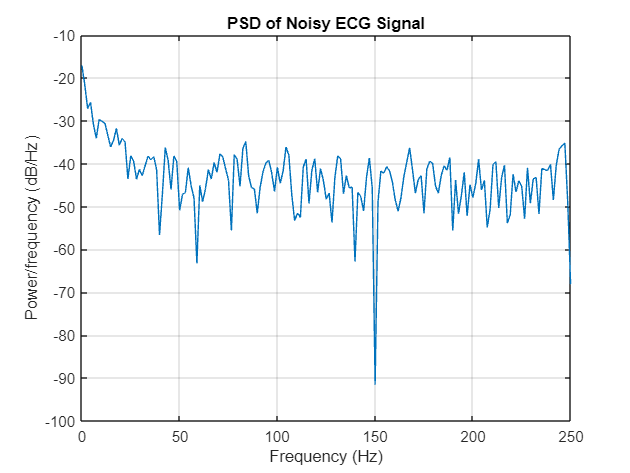

% Plot the power spectral density (PSD)

% Define the window
window = hamming(length(nECG));

% Number of FFT points
nfft = length(nECG);

% Power Spectral Density
figure;
periodogram(nECG, window, nfft, fs);
title('PSD of Noisy ECG Signal');

% Construct moving average filter


ma3ECG_1 = MA_3(nECG);

disp(ma3ECG_1);

    0.0763    0.2627    0.1557    0.1685    0.1043    0.1426    0.0876    0.0886    0.2928    0.4263    0.3546    0.3310    0.2449    0.2977    0.1995    0.1600    0.1579    0.1908    0.2589    0.3232    0.2891    0.1794    0.1492    0.1884    0.2586    0.2722    0.2356    0.2039    0.1748    0.1136    0.1652    0.1065    0.0949    0.0240   -0.0518    0.0521    0.0987    0.1899    0.1883    0.1056    0.1355    0.0703    0.1570    0.1764    0.1521    0.1390    0.1209    0.1861    0.2359    0.2922    0.2332    0.1940    0.0995    0.0901    0.0881    0.2040    0.2209    0.2405    0.1728    0.2588    0.2046    0.2220    0.2032    0.2969    0.3591    0.3358    0.2209    0.1164    0.0571    0.2060    0.1999    0.2664    0.1531    0.2101    0.1420    0.0878   -0.0114    0.0384    0.0872    0.1364    0.1743    0.1926    0.2080    0.2132    0.1658    0.1846    0.1513    0.1724    0.1505    0.0657    0.0276    0.0246    0.1074    0.2708    0.2499    0.2445    0.1558    0.1341    0.1488    0.1290

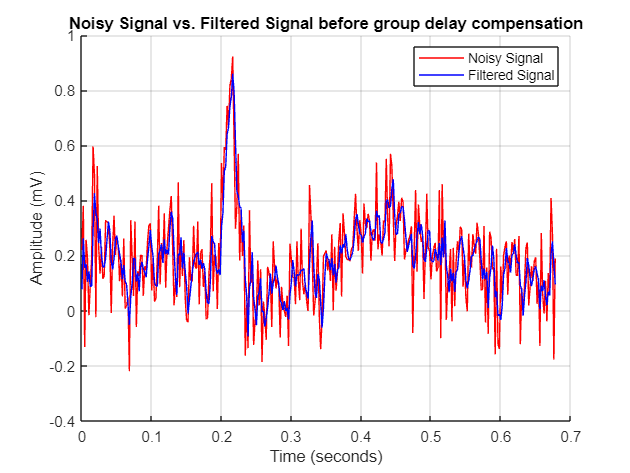


% Plotting the noisy signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time, nECG, 'r-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time, ma3ECG_1, 'b-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal before group delay compensation');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

% Group Delay
MA3_window_size = 3;
tu = (MA3_window_size-1)/2;

fprintf('Group Delay = %i\n', tu);

Group Delay = 1


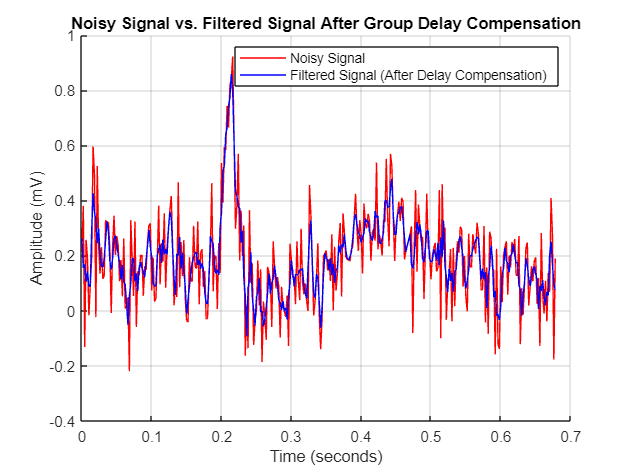

% Delay Compensation
% Shift the filtered signal by the group delay (tu)
ma3ECG_1 = circshift(ma3ECG_1, -1);  

% Plotting the delay-compensated filtered signal
figure;
hold on;  % Keep the current plot
plot(time, nECG, 'r-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red
plot(time, ma3ECG_1, 'b-', 'DisplayName', 'Filtered Signal (After Delay Compensation)');  % Filtered signal in solid blue
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal After Group Delay Compensation');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

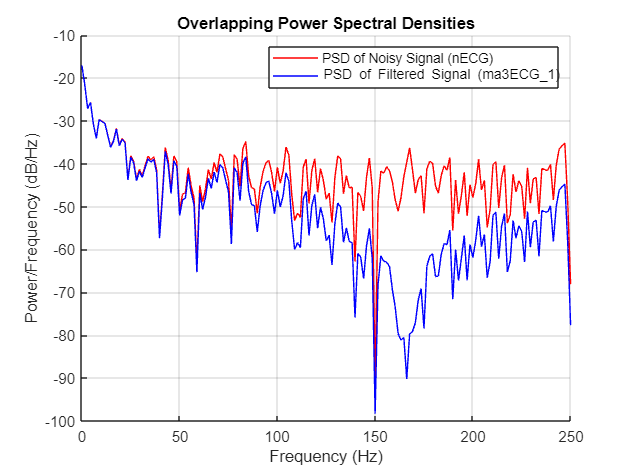

% Overlapping PSDs of ma3ECG_1 and nECG

figure;
hold on;  % Keep the current plot
[pxx_nECG, f_nECG] = periodogram(nECG, window, nfft, fs);
plot(f_nECG, 10*log10(pxx_nECG), 'r-', 'DisplayName', 'PSD of Noisy Signal (nECG)');

% Calculate and plot PSD of ma3ECG_1
[pxx_ma3ECG_1, f_ma3ECG_1] = periodogram(ma3ECG_1, window, nfft, fs);
plot(f_ma3ECG_1, 10*log10(pxx_ma3ECG_1), 'b-', 'DisplayName', 'PSD of Filtered Signal (ma3ECG\_1)');

% Adding labels and title
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Overlapping Power Spectral Densities');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

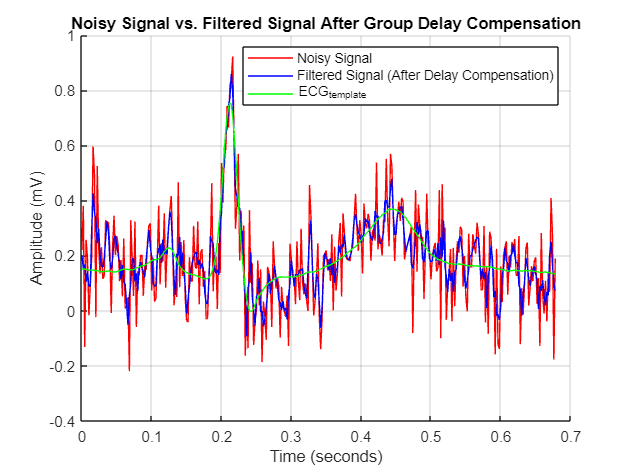

% Filter implementation with matlab built-in function
window_size = 3;
b = (1/window_size)*ones(1,window_size);
a = 1;

ma3ECG_2 = filter(b, a, nECG);
ma3ECG_2 = circshift(ma3ECG_2, -1);

% Plot nECG, ECG_template and ma3ECG_2
figure;
hold on;  % Keep the current plot
plot(time, nECG, 'r-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red
plot(time, ma3ECG_2, 'b-', 'DisplayName', 'Filtered Signal (After Delay Compensation)');  % Filtered signal in solid blue
plot(time, ECG, 'g-', 'DisplayName', 'ECG_template')
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal After Group Delay Compensation');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

% Use fvtool to inspect filter characteristics
fvtool(b, a);

window_size = 10;
b_10 = (1/window_size)*ones(1,window_size);
a_10 = 1;

fvtool(b_10, a_10);

ma10ECG = filter(b, a, nECG);

tu_10 = (window_size - 1)/2;

ma10ECG = circshift(ma10ECG, -ceil(tu_10));

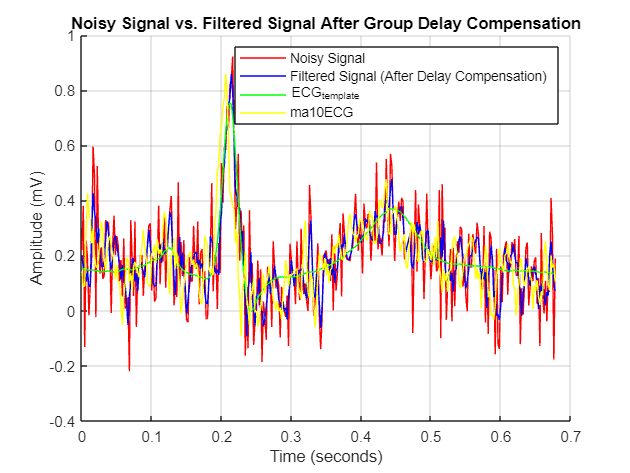

% Plot nECG, ECG_template, ma3ECG_2 and ma10ECG
figure;
hold on;  % Keep the current plot
plot(time, nECG, 'r-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red
plot(time, ma3ECG_2, 'b-', 'DisplayName', 'Filtered Signal (After Delay Compensation)');  % Filtered signal in solid blue
plot(time, ECG, 'g-', 'DisplayName', 'ECG_template')
plot(time, ma10ECG, 'y-', 'DisplayName', 'ma10ECG');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal After Group Delay Compensation');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

Orders = 1 : 50;
MSE_values = zeros(1, length(Orders));

for i = 1 : length(Orders)
    N = i;
    MSE_values(i) = MSE_MA_filter(ECG, nECG, N);
end

disp(MSE_values);

    0.0174    0.0085    0.0058    0.0043    0.0033    0.0028    0.0024    0.0022    0.0021    0.0020    0.0019    0.0019    0.0020    0.0021    0.0022    0.0024    0.0026    0.0027    0.0029    0.0031    0.0034    0.0036    0.0039    0.0041    0.0044    0.0046    0.0049    0.0051    0.0054    0.0056    0.0059    0.0061    0.0063    0.0065    0.0067    0.0070    0.0071    0.0074    0.0075    0.0077    0.0079    0.0080    0.0082    0.0084    0.0085    0.0086    0.0087    0.0089    0.0090    0.0091




% Find the minimum value and its index
[minMSE, minIndex] = min(MSE_values);

fprintf('Minimum Value: %d\n', minMSE);

Minimum Value: 1.935368e-03


fprintf('Index of Minimum Value: %d\n', minIndex);

Index of Minimum Value: 12


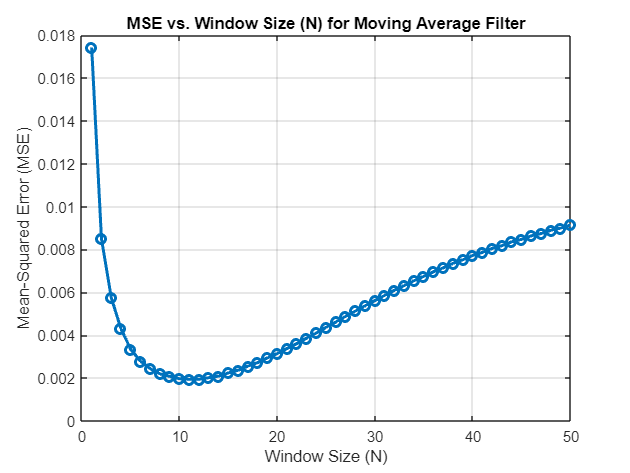


% Plot MSE vs. N
figure;
plot(Orders, MSE_values, '-o', 'LineWidth', 2);
xlabel('Window Size (N)');
ylabel('Mean-Squared Error (MSE)');
title('MSE vs. Window Size (N) for Moving Average Filter');
grid on;

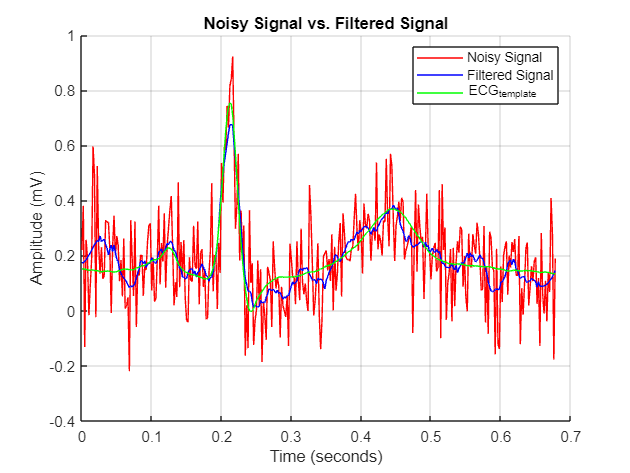

% Savitzky-Golay SG(N,L) filter

% Apply SG(3,11) filter

N = 3;
L = 11;
L_ = 2*L+1;

sg310ECG = sgolayfilt(nECG, N, L_);

% Plot nECG, ECG_template and sg310ECG
figure;
hold on;  % Keep the current plot
plot(time, nECG, 'r-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red
plot(time, sg310ECG, 'b-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue
plot(time, ECG, 'g-', 'DisplayName', 'ECG_template')
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

% Optimum SG(N,L) filter implementation
N_values =  0:25;
L_values = 1: 25;

MSE_values = ones(length(N_values), length(L_values)).*inf;


for i = 1 : length(L_values)
    L = L_values(i);
    for j = 1 : length(N_values)
        N = N_values(j);
        MSE_values(j,i) = MSE_SG_filter(ECG, nECG, N, L);
    end
end

disp(MSE_values)

    0.0057    0.0033    0.0024    0.0020    0.0018    0.0020    0.0022    0.0024    0.0028    0.0033    0.0037    0.0042    0.0048    0.0052    0.0056    0.0060    0.0064    0.0068    0.0071    0.0074    0.0077    0.0080    0.0082    0.0085    0.0087
    0.0058    0.0033    0.0024    0.0020    0.0018    0.0019    0.0021    0.0024    0.0028    0.0032    0.0037    0.0042    0.0047    0.0052    0.0057    0.0062    0.0067    0.0070    0.0074    0.0077    0.0080    0.0082    0.0085    0.0087    0.0089
    0.0174    0.0083    0.0058    0.0044    0.0034    0.0028    0.0025    0.0022    0.0019    0.0018    0.0018    0.0018    0.0018    0.0019    0.0021    0.0023    0.0025    0.0027    0.0028    0.0031    0.0034    0.0037    0.0040    0.0042    0.0045
       Inf    0.0085    0.0058    0.0044    0.0036    0.0029    0.0025    0.0021    0.0019    0.0018    0.0017    0.0018    0.0019    0.0019    0.0021    0.0022    0.0024    0.0027    0.0031    0.0033    0.0036    0.0039    0.0042    0.0045    0.0

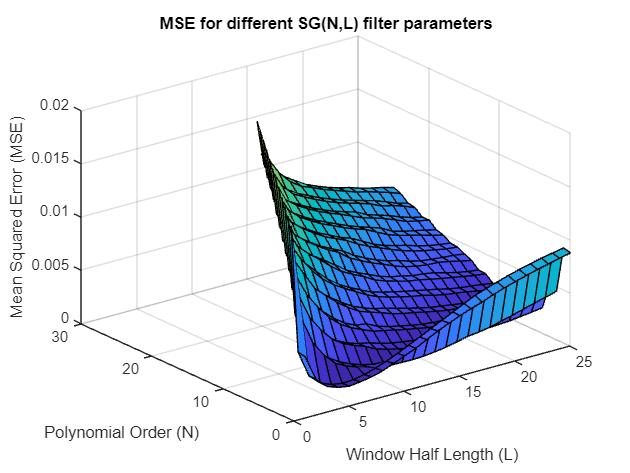


% Visualize the MSE values using a surface plot
figure;
surf(L_values, N_values, MSE_values);
xlabel('Window Half Length (L)');
ylabel('Polynomial Order (N)');
zlabel('Mean Squared Error (MSE)');
title('MSE for different SG(N,L) filter parameters');


% Find the minimum MSE and corresponding indices for N and L
[min_MSE, idx] = min(MSE_values(:));  % Get the minimum MSE
[row_idx, col_idx] = ind2sub(size(MSE_values), idx);  % Convert linear index to subscripts

% Extract the optimal N and L values
opt_N = N_values(row_idx);
opt_L = L_values(col_idx);

% Display the optimum parameters
disp(['Optimum N (Polynomial Order): ', num2str(opt_N)]);

Optimum N (Polynomial Order): 4


disp(['Optimum L (Window half Length): ', num2str(opt_L)]);

Optimum L (Window half Length): 17


disp(['Minimum MSE: ', num2str(min_MSE)]);

Minimum MSE: 0.0017074


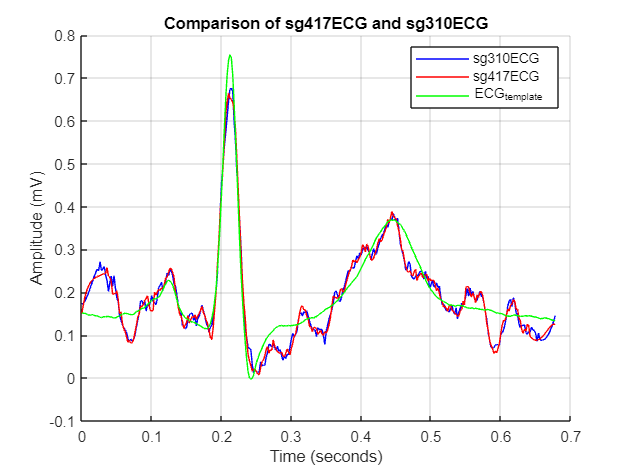

% Savitzky-Golay filter for optimum parameters 
% SG(4,17)

sg417ECG = sgolayfilt(nECG, 4, 2*17+1);

% Plot ECG_template, sg310ECG and sg417ECG
figure;
hold on;  % Keep the current plot
plot(time, sg310ECG, 'b-', 'DisplayName', 'sg310ECG');  % Filtered signal in solid blue
plot(time, sg417ECG, 'r-', 'DisplayName', 'sg417ECG');  % Noisy signal in red
plot(time, ECG, 'g-', 'DisplayName', 'ECG_template')
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Comparison of sg417ECG and sg310ECG');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot